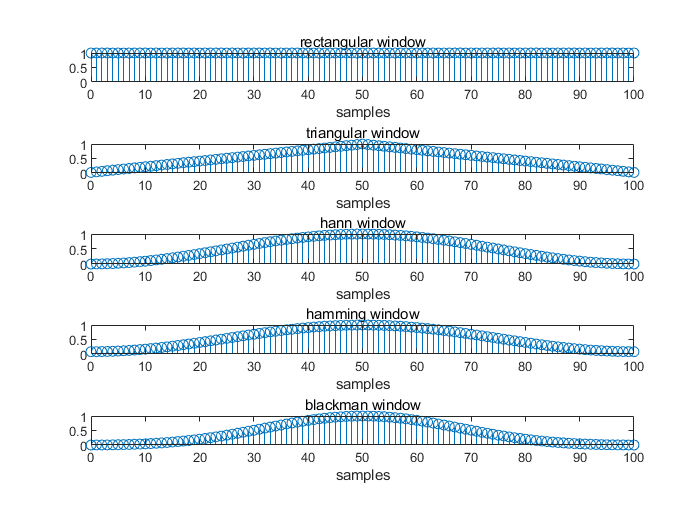

L=101;
re=rectwin(L);
tr=triang(L);
han=hann(L);
ham=hamming(L);
bl=blackman(L);
figure
subplot(5,1,1);
stem(0:1:L-1,re);
xlabel('samples');
title('rectangular window');
subplot(5,1,2);
stem(0:1:L-1,tr);
xlabel('samples');
title('triangular window');
subplot(5,1,3);
stem(0:1:L-1,han);
xlabel('samples');
title('hann window');
subplot(5,1,4);
stem(0:1:L-1,ham);
xlabel('samples');
title('hamming window');
subplot(5,1,5);
stem(0:1:L-1,bl);
xlabel('samples');
title('blackman window');

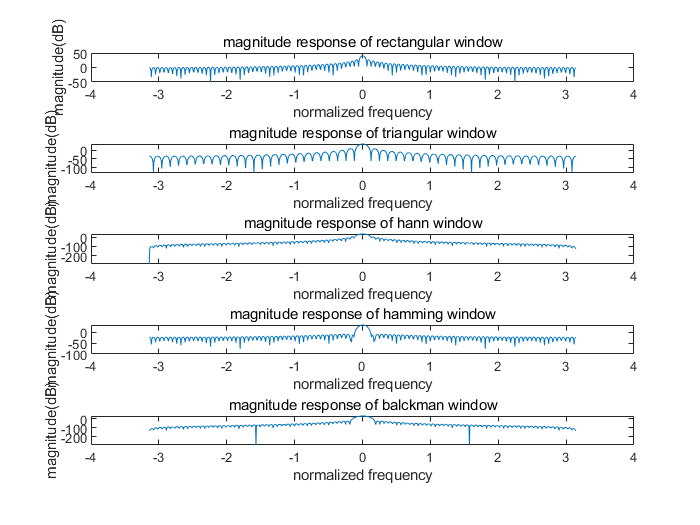


Lf=2^10;
RE=fft(re,Lf);
TR=fft(tr,Lf);
HAN=fft(han,Lf);
HAM=fft(ham,Lf);
BL=fft(bl,Lf);
figure
subplot(5,1,1);
plot(-pi:2*pi/(Lf-1):pi,mag2db(abs(fftshift(RE))));
xlabel('normalized frequency');
ylabel('magnitude(dB)');
title('magnitude response of rectangular window');
subplot(5,1,2);
plot(-pi:2*pi/(Lf-1):pi,mag2db(abs(fftshift(TR))));
xlabel('normalized frequency');
ylabel('magnitude(dB)');
title('magnitude response of triangular window');
subplot(5,1,3);
plot(-pi:2*pi/(Lf-1):pi,mag2db(abs(fftshift(HAN))));
xlabel('normalized frequency');
ylabel('magnitude(dB)');
title('magnitude response of hann window');
subplot(5,1,4);
plot(-pi:2*pi/(Lf-1):pi,mag2db(abs(fftshift(HAM))));
xlabel('normalized frequency');
ylabel('magnitude(dB)');
title('magnitude response of hamming window');
subplot(5,1,5);
plot(-pi:2*pi/(Lf-1):pi,mag2db(abs(fftshift(BL))));
xlabel('normalized frequency');
ylabel('magnitude(dB)');
title('magnitude response of balckman window');

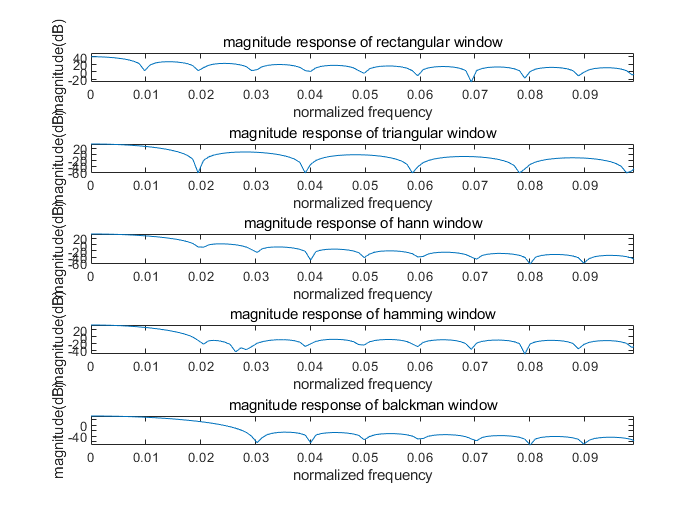


figure
subplot(5,1,1);
plot((0:Lf-1)*1/Lf,mag2db(abs(RE)));
xlabel('normalized frequency');
ylabel('magnitude(dB)');
title('magnitude response of rectangular window');
xlim([0,5*2/L]);
subplot(5,1,2);
plot((0:Lf-1)*1/Lf,mag2db(abs(TR)));
xlabel('normalized frequency');
ylabel('magnitude(dB)');
title('magnitude response of triangular window');
xlim([0,5*2/L]);
subplot(5,1,3);
plot((0:Lf-1)*1/Lf,mag2db(abs(HAN)));
xlabel('normalized frequency');
ylabel('magnitude(dB)');
title('magnitude response of hann window');
xlim([0,5*2/L]);
subplot(5,1,4);
plot((0:Lf-1)*1/Lf,mag2db(abs(HAM)));
xlabel('normalized frequency');
ylabel('magnitude(dB)');
title('magnitude response of hamming window');
xlim([0,5*2/L]);
subplot(5,1,5);
plot((0:Lf-1)*1/Lf,mag2db(abs(BL)));
xlabel('normalized frequency');
ylabel('magnitude(dB)');
title('magnitude response of balckman window');
xlim([0,5*2/L]);